# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 7.6.1 Spatial Resolution

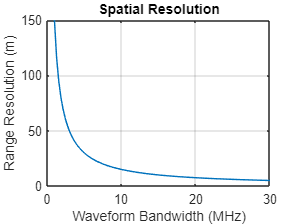

% Set the waveform bandwidth (Hz)
bandwidth = linspace(1e6, 30e6);

% Speed of light (m/s)
speed_of_light = 299792458;

% Plot the range resolution
figure;
plot(bandwidth / 1e6, speed_of_light ./ (2 * bandwidth))
title('Spatial Resolution')
xlabel('Waveform Bandwidth (MHz)')
ylabel('Range Resolution (m)')
grid on

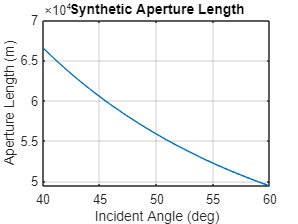


% Set the sensor altitude (m)
altitude = 570e3;

% Set the sensor incident angle (deg)
incident_angle = linspace(40, 60);

% Set the operating wavelength (m)
wavelength = 0.3;

% Set the azimuth resolution (m)
delta_az = 2;

% Calculate the slant range (m)
slant_range = altitude ./ cosd(90 - incident_angle);

% Calculate the synthetic aperture integration angle
theta = wavelength / (2 * delta_az);

% Calculate and plot the synthetic aperture length (m)
length_sa = 2 * slant_range * tan(theta / 2);

figure;
plot(incident_angle, length_sa)
title('Synthetic Aperture Length')
xlabel('Incident Angle (deg)')
ylabel('Aperture Length (m)')
grid on